% 0 is traning mode for training the SVM module 
% 1 is testing mode for recognizing the separated Image 2: hello_world.jpg 
% You have to train the SVM model first
mode = "0"

mode = "0"

pre_processing = false

pre_processing = logical
   0


hyperparameter_tuning = true

hyperparameter_tuning = logical
   1


% Set the dataset path
dataFolder = 'p_dataset_26'; % Replace with the actual data path
segFolder = 'seg_dataset'; % Replace with the actual data path
KernelFunctionType = 'linear'

KernelFunctionType = 'linear'

boxConstraint = 1

boxConstraint = 1

% Load the dataset, using folder names as labels
imds = imageDatastore(dataFolder, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');
segImgs = imageDatastore(segFolder, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');
% Check if the files were successfully loaded
imds.Files(5000);


% Split the dataset into 75% training and 25% testing
[imdsTrain, imdsTest] = splitEachLabel(imds, 0.75, 'randomized');

% Display the number of images in each category in the training and testing sets
countEachLabel(imdsTrain);
countEachLabel(imdsTest);

% Check the number of training images
numTrainImages = numel(imdsTrain.Files);
disp(['Number of training images: ', num2str(numTrainImages)]);

Number of training images: 5334



% Set target image size
inputSize = [28, 28]; 

% Create augmented data storage to automatically resize images to the target size
augmentedDataTrain = augmentedImageDatastore(inputSize, imdsTrain, 'ColorPreprocessing', 'gray2rgb');
augmentedDataTest = augmentedImageDatastore(inputSize, imdsTest, 'ColorPreprocessing', 'gray2rgb');
augmentedDataSeg = augmentedImageDatastore(inputSize, segImgs, 'ColorPreprocessing', 'gray2rgb');

% Here, each image is flattened into a row vector and stored in the featuresTrain and featuresTest matrices,
% where each row represents the feature vector of an image.
% Initialize matrices to store features and labels
featuresTrain = [];
labelsTrain = [];
featuresTest = [];
labelsTest = [];
featuresSeg = [];
labelsSeg = [];
[featuresTrain, labelsTrain] = extractFeaturesAndLabels(augmentedDataTrain);
[featuresTest, labelsTest] = extractFeaturesAndLabels(augmentedDataTest);
[featuresSeg, labelsSeg] = extractFeaturesAndLabels(augmentedDataSeg)

featuresSeg = 2×1444 uint8 矩阵
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


labelsSeg = 2×1 categorical 数组
     seg_dataset 
     seg_dataset 



% Check the size of the features and labels
size(featuresTrain)

ans =         5334        1444


size(labelsTrain)

ans =         5334           1


size(featuresTest)

ans =         1778        1444


size(labelsTest)

ans =         1778           1


predictedLabels = 1778×1 categorical 数组
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 
     SampleD 


Test Accuracy: 0.98088


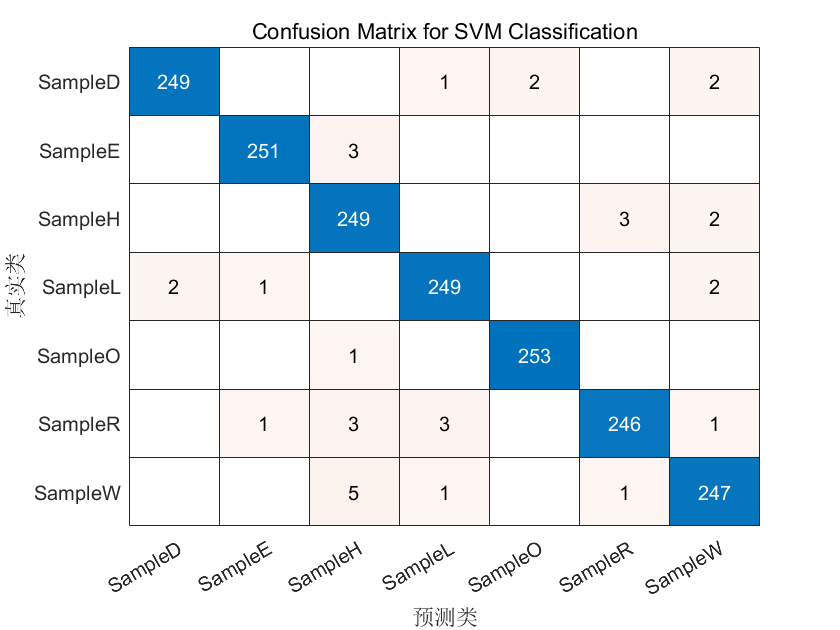


% Convert feature matrices to double type
featuresTrain = double(featuresTrain);
featuresTest = double(featuresTest);
featuresSeg = double(featuresSeg);

% Train a multi-class SVM model using fitcecoc

%svmModelPre = fitcecoc(featuresTrain, labelsTrain, 'Learners', templateSVM('KernelFunction', 'linear'));

% combo 2: RBF kernel，BoxConstraint = 1
%svmModelPre2 = fitcecoc(featuresTrain, labelsTrain, 'Learners', templateSVM('KernelFunction', 'rbf', 'BoxConstraint', 1));

% combo 3: polynomial kernel，BoxConstraint = 1
%svmModelPre3 = fitcecoc(featuresTrain, labelsTrain, 'Learners', templateSVM('KernelFunction', 'polynomial', 'BoxConstraint', 1));

% combo 4: linear kernel，BoxConstraint = 10
svmModel4 = fitcecoc(featuresTrain, labelsTrain, 'Learners', templateSVM('KernelFunction', 'linear', 'BoxConstraint', 10));


% Testing Mode
if(mode =="1")
    % Make predictions using the trained model
    predictedLabels = predict(svmModelPre, featuresSeg)
end

% Training Mode
if(mode =="0")
    % Make predictions using the trained model
    predictedLabels = predict(svmModel4, featuresTest)
    % Calculate accuracy
    accuracy = sum(predictedLabels == labelsTest) / numel(labelsTest);
    disp(['Test Accuracy: ', num2str(accuracy)]);
    
    % Create a confusion matrix
    confusionchart(labelsTest, predictedLabels);
    title('Confusion Matrix for SVM Classification');
end

function [features, labels] = extractFeaturesAndLabels(augimds)
    % Initialize empty matrices to store features and labels
    features = [];
    labels = [];

    % Loop through all batches of data
    while hasdata(augimds)
        dataBatch = read(augimds); % Read the current batch of data (usually 128 samples)

        % Loop through each sample in the current batch
        for i = 1:height(dataBatch)
            img = dataBatch.input{i}; % Get the image data
            paddingSize = [5, 5]; % Padding
            img = padarray(img, paddingSize, 0, 'both'); % Around the picture all with all black pix

            imgGray = rgb2gray(img); % Convert to grayscale
            imgVector = imgGray(:)'; % Flatten into a vector
            features = [features; imgVector]; % Add to the features matrix

            % Add the corresponding label
            labels = [labels; dataBatch.response(i)];
        end
    end
end

